# Plots of ICO logs for distance ICO's and angle ICO

clc; clear;

## Distance ICO's

Contains plot of the logs of the one ICO for distance control and two ICO's for distance control

### One ICO:

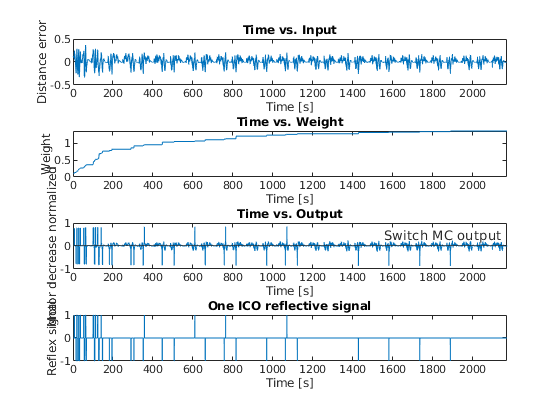

% Load files
ico_one_mc = load('../docker/ros-fence-inspection/assets/ico_logs/ico_one_mc.txt');
ico_mc_col = load('../docker/ros-fence-inspection/assets/ico_logs/ico_mc_col.txt');


time = ico_one_mc(:,2);
input = ico_one_mc(:,3);
weight = ico_one_mc(:,4);
output = ico_one_mc(:,5);
x_range = [0 max(time)];

figure(1)
subplot(4,1,1);
plot(time, input);
title('Time vs. Input')
xlabel('Time [s]')
ylabel('Distance error')
xlim(x_range)

subplot(4,1,2);
plot(time, weight);
title('Time vs. Weight')
xlabel('Time [s]')
ylabel('Weight')
xlim(x_range)

subplot(4,1,3);
plot(time, output);
title('Time vs. Output')
xlabel('Time [s]')
ylabel('Motor decrease normalized')
yline(0,'-','Switch MC output')
xlim(x_range)

subplot(4,1,4);
plot(time, ico_mc_col(:,3))
title('One ICO reflective signal')
xlabel('Time [s]')
ylabel('Reflex signal')
xlim(x_range)

### Two ICO's:

% Load files
ico_two_mc = load('../docker/ros-fence-inspection/assets/ico_logs/ico_two_mc.txt');

Error using load
File ../docker/ros-fence-inspection/assets/ico_logs/ico_two_mc.txt is in use by another process or thread. You should be able to load data once the other process or thread has released the file.

ico_mc_col = load('../docker/ros-fence-inspection/assets/ico_logs/ico_mc_col.txt');

time = ico_two_mc(:,2);

input_left = ico_two_mc(:,3);
input_right = ico_two_mc(:,4);
weight_left = ico_two_mc(:,5);
weight_right = ico_two_mc(:,6);
output_left = ico_two_mc(:,7);
output_right = ico_two_mc(:,8);

col_left = ico_mc_col(:,3);
col_right = ico_mc_col(:,4);

x_range = [0 max(time)];

figure(1)
subplot(4,1,1);
plot(time, input_left, time, input_right);
title('Time vs. Input')
xlabel('Time [s]')
ylabel('Distance error')
xlim(x_range)

subplot(4,1,2);
plot(time, weight_left, time, weight_right);
title('Time vs. Weight')
xlabel('Time [s]')
ylabel('Weight')
xlim(x_range)

subplot(4,1,3);
plot(time, output_left, time, output_right);
title('Time vs. Output')
xlabel('Time [s]')
ylabel('Motor value normalized')
xlim(x_range)

subplot(4,1,4);
plot(time, col_left, time, col_right)
title('One ICO reflective signal')
xlabel('Time [s]')
ylabel('Reflex signal')
xlim(x_range)

## Angle ICO

Contains plot of the logs of the one ICO for stabilizing the distance ICO to counteract overshoot, due to deaccelleration and accelleartion curves of the frobit.

% Load files
ico_ang = load('../docker/ros-fence-inspection/assets/ico_logs/ico_ang.txt');
ico_ang_col = load('../docker/ros-fence-inspection/assets/ico_logs/ico_ang_col.txt');

figure(3)
time = ico_ang(:,2);
input = ico_ang(:,3);
weight = ico_ang(:,4);
output = ico_ang(:,5);

subplot(3,1,1);
plot(time, input);
title('Time vs. Input')
xlabel('Time [s]')
ylabel('Angle normalized')

subplot(3,1,2);
plot(time, weight);
title('Time vs. Weight')
xlabel('Time [s]')
ylabel('Weight')

subplot(3,1,3);
plot(time, output);
title('Time vs. Output')
xlabel('Time [s]')
ylabel('Motor decrease normalized')

figure(4)
plot(time, ico_ang_col(:,3))
title('ICO Angle reflective signal')
xlabel('Time [s]')
ylabel('Reflex signal')